# ** GRN Project 1**

Consider the simplified Guido-Collins system with an activator transcription factor and an inhibitor transcription factor. 

You may use the code `GuidoCollins_simplified01.m` Section 2.3

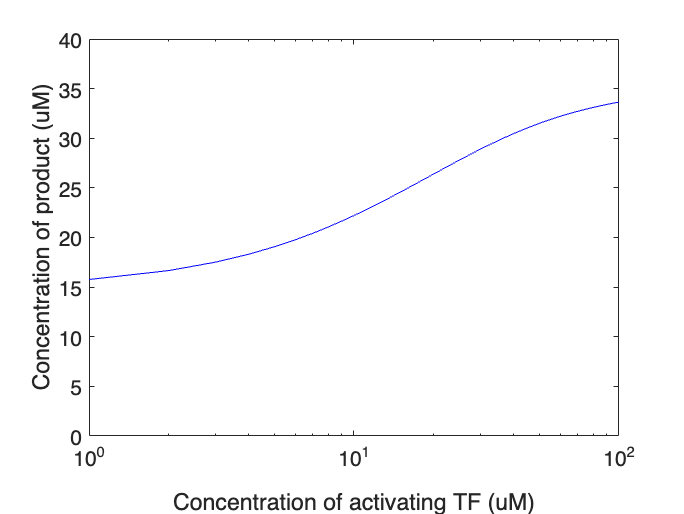

%% 2.3 Parameter sweep across activator concentration

paramArray = 0:1:100;

%paramArray = logspace(-1,3,200); % Uncomment to make a log plot

g_storage = zeros(size(paramArray));

for iParam=1:numel(paramArray)
    
    % parameters
    kon = 0.001; % s^-1 uM^-1
    koff = 0.0005; % s^-1

    delta_m = 0.05;
    gamma_p = 0.02;
    delta_p = 0.01;

    gamma_m =@(p0,pr,pa,par) 1.0*p0+0.0*pr+2.0*pa+1.0*par;

    I = 10; % concentration of inhibitory transcription factor (uM) % EDIT for HW1
    C = paramArray(iParam); % concentration of activatory transcription factor (uM) % EDIT for HW1

    M =@(t) [-kon*C-kon*I, +koff*I      ,          koff,       0;
                   +kon*I, -koff*I-kon*C,             0,   +koff;
                   +kon*C,             0,   -koff-kon*I,   +koff;
                        0,        +kon*C,         kon*I, -2*koff];


    dmdt =@(p0,pr,pa,par,m,p,t) +gamma_m(p0,pr,pa,par) - delta_m*m;
    dpdt =@(p0,pr,pa,par,m,p,t) +gamma_p*m - delta_p*p;

    initialCondition = [1,0,0,0,0,0];

    dxdt = @(t,x)[M(t)*[x(1);x(2);x(3);x(4)];
                   dmdt(x(1),x(2),x(3),x(4),x(5),x(6));
                   dpdt(x(1),x(2),x(3),x(4),x(5),x(6))];
    
    [T, X] = ode45(dxdt, [0.0,100], initialCondition);
    
    g_storage(iParam) = X(end,6);
    
end

figure; clf;
plot(paramArray,g_storage, '-b')
xlabel('Concentration of activating TF (uM)') %
ylabel('Concentration of product (uM)')
set(gca,'ylim', [0,40]);
set(gca,'xscale','log') % uncomment to make a log plot

# HW1 PART 1

Assume the concentration of inhibitor is fixed at 10uM.  

Plot the steady-state amount of Protein as a function of the activator concentration, but make the axis showing concentration of activator a logarithmic axis.

What is the concentration of activator that results in half its maximal effect? This is called the EC50 of the activator.

EC50=10uM

# HW1 PART 2

Assume the concentration of activator is fixed at 10uM. 

Plot the steady-state amount of Protein as a function of the inhibitor concentration.

What is the concentration of inhibitor that results in half its maximal inhibition? This is called the IC50 of the inhibitor. 

IC50=13uM

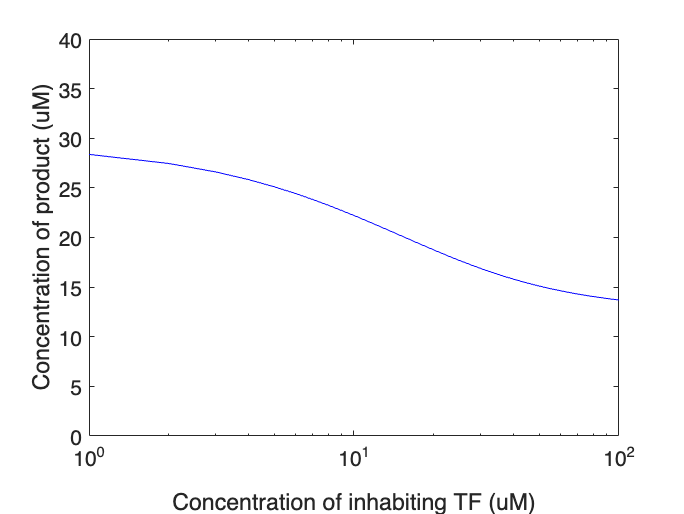


%% 2.3 Parameter sweep across activator concentration

paramArray = 0:1:100;

%paramArray = logspace(-1,3,200); % Uncomment to make a log plot

g_storage = zeros(size(paramArray));

for iParam=1:numel(paramArray)
    
    % parameters
    kon = 0.001; % s^-1 uM^-1
    koff = 0.0005; % s^-1

    delta_m = 0.05;
    gamma_p = 0.02;
    delta_p = 0.01;

    gamma_m =@(p0,pr,pa,par) 1.0*p0+0.0*pr+2.0*pa+1.0*par;

    I = paramArray(iParam); % concentration of inhibitory transcription factor (uM) % EDIT for HW1
    C = 10; % concentration of activatory transcription factor (uM) % EDIT for HW1

    M =@(t) [-kon*C-kon*I, +koff*I      ,          koff,       0;
                   +kon*I, -koff*I-kon*C,             0,   +koff;
                   +kon*C,             0,   -koff-kon*I,   +koff;
                        0,        +kon*C,         kon*I, -2*koff];


    dmdt =@(p0,pr,pa,par,m,p,t) +gamma_m(p0,pr,pa,par) - delta_m*m;
    dpdt =@(p0,pr,pa,par,m,p,t) +gamma_p*m - delta_p*p;

    initialCondition = [1,0,0,0,0,0];

    dxdt = @(t,x)[M(t)*[x(1);x(2);x(3);x(4)];
                   dmdt(x(1),x(2),x(3),x(4),x(5),x(6));
                   dpdt(x(1),x(2),x(3),x(4),x(5),x(6))];
    
    [T, X] = ode45(dxdt, [0.0,100], initialCondition);
    
    g_storage(iParam) = X(end,6);
    
end

figure; clf;
plot(paramArray,g_storage, '-b')
xlabel('Concentration of inhabiting TF (uM)') % EDIT for HW1
ylabel('Concentration of product (uM)')
set(gca,'ylim', [0,40]);

set(gca,'xscale','log') % uncomment to make a log plot